# challenge

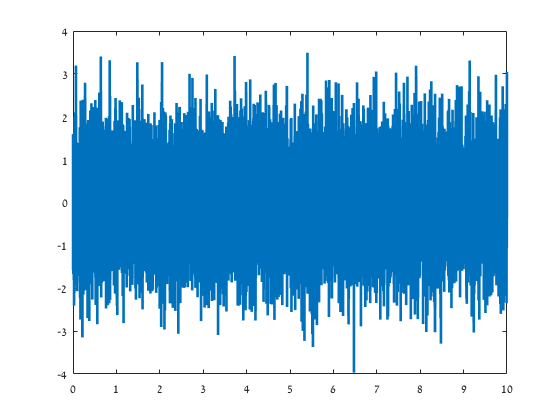

clear; clc;clf;
load filtering_codeChallenge.mat

nyquist = fs/2;
frange1  = [6 17];
order1   = round( 10*fs/frange1(1) );
% filter kernel
filtkern1 = fir1(order1,frange1/nyquist);

frange2  = [25 32];
order2   = round( 10*fs/frange2(1) );
% filter kernel
filtkern2 = fir1(order2,frange2/nyquist);

% compute the power spectrum of the filter kernel
filtpow = abs(fft(filtkern1)).^2;
% compute the frequencies vector and remove negative frequencies
hz      = linspace(0,fs/2,floor(length(filtkern1)/2)+1);
filtpow = filtpow(1:length(hz));


figure(2)
N = length(x);
t = (0:N-1)/fs;
hz = linspace(0,fs,N);
plot(t,x,'linew',2);

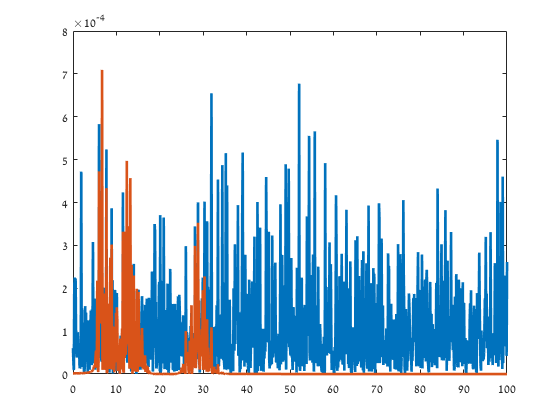

figure(3)
plot(hz,abs(fft(x)/N).^2,'linew',2);
hold on
plot(hz,abs(fft(y)/N).^2,'linew',2);
set(gca,'xlim',[0 100])

## filter

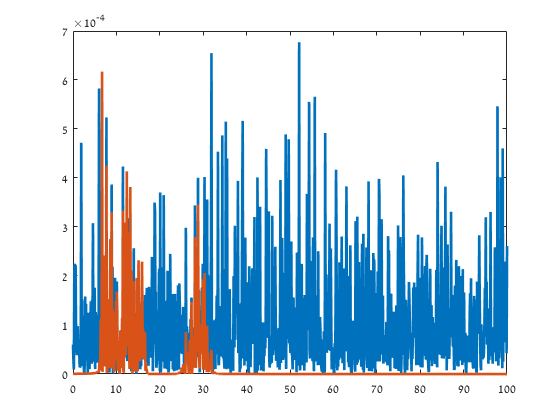

fdata1 = filtfilt(filtkern1,1,x);
fdata2 = filtfilt(filtkern2,1,x);
fdata = fdata1+fdata2;
figure(4)
plot(hz,abs(fft(x)/N).^2,'linew',2);
hold on
plot(hz,abs(fft(fdata)/N).^2,'linew',2);
set(gca,'xlim',[0 100])

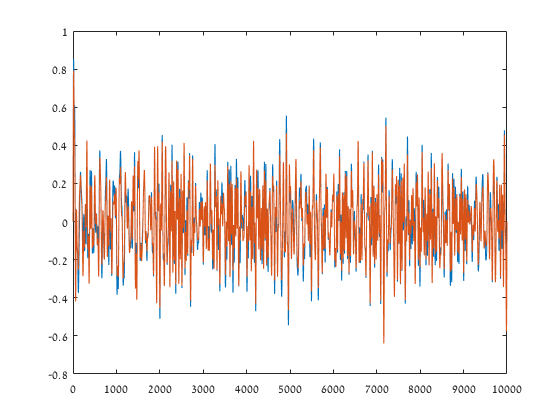

figure(5)
plot(y)
hold on 
plot(fdata)

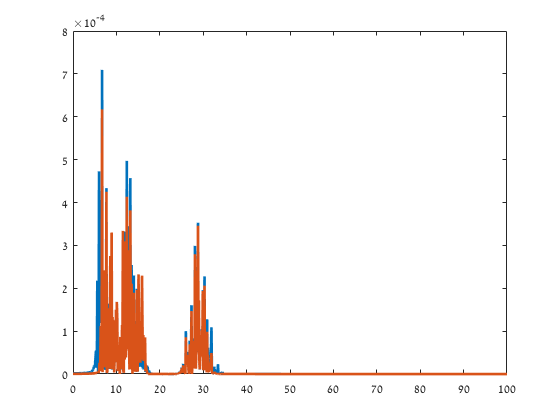

figure(6)
plot(hz,abs(fft(y)/N).^2,'linew',2);
hold on
plot(hz,abs(fft(fdata)/N).^2,'linew',2);
set(gca,'xlim',[0 100])